clear; clc; close all


mew=1000; %kg/m^3
rho=1.225; %air density
c=2; %chord in meters
x_f= 0.48*c; 
a=-0.02*c;
t=0.01; %thickness in meters
l=1; %length in meters
omega_h=4; %plunge natural frequency in HZ
omega_a=10; %pitch natural frequency in HZ
b=c/2; %half of the chord length

m=c*mew*t*l;
I_a=1/12*m*c^2+m*a^2; 
k_plunge= m*(2*pi*omega_h)^2;
k_pitch= I_a*(2*pi*omega_a)^2; %converting to rad/s
%PK method
%loop parameters
du=0.01; %m/s
error_margin=1e-7;
Umin=0.1;
Umax=100; %m/s
%matrixes
K=[k_plunge 0; 0 k_pitch;];
M=[m -m*a; -m*a I_a;];
D=[-rho*pi*b^2 a*rho*pi*b^2; rho*pi*b^2*a -(a^2+b^2/8)*rho*pi*b^2;];
W1 = []; d1 = []; W2 = []; d2 = []; d_all = [];
Urange = Umin:du:Umax;


for U= Urange
    ii=3;
    for om=[sqrt(k_plunge/m) sqrt(k_pitch/I_a)]
    err =10;
    iter=0;
        while err >=error_margin
          iter=iter+1;
          k=om*b/U;
          C=1-0.165/(1-(0.0455*1i/k))-(0.335/(1-1i*(0.3/k)));
          E=[-2*pi*rho*b*U*C -rho*pi*b^2*U+(a-b/2)*2*pi*rho*b*U*C; rho*pi*b^2*U-rho*pi*b*U*(b-(2*a+b)*C) rho*pi*b*U*(b-(2*a+b)*C)*(a-b/2);];
          F=[0 -2*pi*rho*b*U^2*C; 0 rho*pi*b^2*U^2-rho*pi*b*U^2*(b-(2*a+b)*C)];
          A=[zeros(2) eye(2);(M-D)\(F-K) (M-D)\E;]; 
          d=eig(A);
          [d_imag, index] = sort(imag(d), 'ascend'); %sort eigenvalues in ascending order 
          d_imag1 = d_imag(ii); % if heave/pitch, then extract the imaginary of second largest/largest
          err = abs(d_imag1-om); % Calculate error of computed imaginary (d_imag1) against the assumed freq (om) in the first step
          om = d_imag1;
        end
    d_sorted=d(index);
    %W stores natural frequencies
    %d stores damping ratios
    %d_all stores all eigenvalues of all airspeeds. 
    if ii==3;W1=[W1 abs(d_sorted(ii))]; d1 = [d1 -real(d_sorted(ii))/abs(d_sorted(ii))]; end
    if ii == 4; W2 = [W2 abs(d_sorted(ii))]; d2 = [d2 -real(d_sorted(ii))/abs(d_sorted(ii))]; end
    d_all=[d_all d_sorted]; %this stores all of the eigenvalues for the two modes
    ii=ii+1;
    end
end
%need to find where the first eigenvalue crosses into the right half plane
%ie. where the damping ratio becomes negative. 
ind=1;
running=true;
double mode;
while running
    if d1(1,ind)<=0; running=false; mode=1; break; end
    if d2(1,ind)<=0; running=false; mode=2; break; end
    ind=ind+1;
end
Uflutter=Urange(1,ind)

Uflutter = 82.9400

flutterfrequency=0;
if mode==1;flutterfrequency=W1(ind);end
if mode==2;flutterfrequency=W2(ind);end
frequency=flutterfrequency/2/pi %converting to HZ

frequency = 7.2522

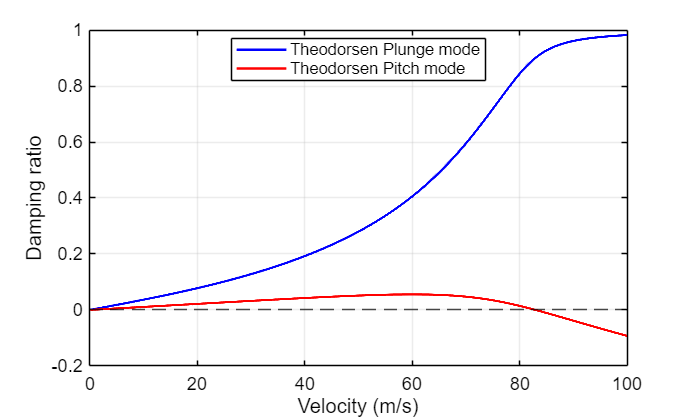




% Figure 1: Damping ratio
fig1 = figure('Color', 'white');
ax1 = axes(fig1);

plot(ax1, Urange, d1, 'b-', Urange, d2, 'r-', 'LineWidth', 1.5);
yline(ax1, 0, 'k--');

xlabel(ax1, 'Velocity (m/s)', 'Color', 'black');
ylabel(ax1, 'Damping ratio', 'Color', 'black');

lgd1 = legend(ax1, 'Theodorsen Plunge mode', ...
    'Theodorsen Pitch mode', 'Location', 'best');
lgd1.Color = 'white';
lgd1.EdgeColor = 'black';
lgd1.TextColor = 'black';

grid(ax1, 'on');
ax1.Color = 'white';
ax1.XColor = 'black';
ax1.YColor = 'black';
ax1.GridColor = [0.7 0.7 0.7];
ax1.FontSize = 11;
ax1.Box = 'on';


% Figure 2: Modal frequency
fig2 = figure('Color', 'white');
ax2 = axes(fig2);

plot(ax2, Urange, W1/2/pi, 'b-', Urange, W2/2/pi, 'r-', 'LineWidth', 1.5);

xlabel(ax2, 'Velocity (m/s)', 'Color', 'black');
ylabel(ax2, 'Modal frequency (Hz)', 'Color', 'black');

lgd2 = legend(ax2, 'Theodorsen Plunge mode', ...
    'Theodorsen Pitch mode', 'Location', 'best');
lgd2.Color = 'white';
lgd2.EdgeColor = 'black';
lgd2.TextColor = 'black';

grid(ax2, 'on');
ax2.Color = 'white';
ax2.XColor = 'black';
ax2.YColor = 'black';
ax2.GridColor = [0.7 0.7 0.7];
ax2.FontSize = 11;
ax2.Box = 'on';


% Export figures
exportgraphics(fig1, 'figure1.png', ...
    'BackgroundColor', 'white', 'Resolution', 300);

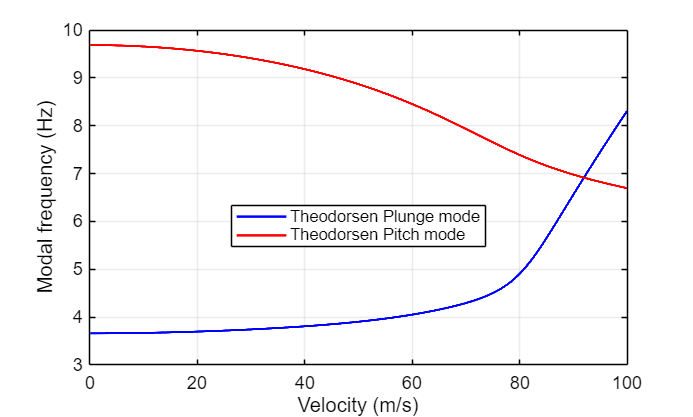


exportgraphics(fig2, 'figure2.png', ...
    'BackgroundColor', 'white', 'Resolution', 300);